% mikeXcohen@gmail.com

## signal created by a sum of sine waves (same as in previous lecture)

% create a few sine waves and sum

% define a sampling rate
srate = 1000;

% list some frequencies
frex = [ 3   10   5   15   35 ];

% list some random amplitudes... make sure there are the same number of
% amplitudes as there are frequencies!
amplit = [ 5   15   10   5   7 ];

% phases... list some random numbers between -pi and pi
phases = [  pi/7  pi/8  pi  pi/2  -pi/4 ];

% define time...
time = -1:1/srate:1;


% now we loop through frequencies and create sine waves
sine_waves = zeros(length(frex),length(time));
for fi=1:length(frex)
    sine_waves(fi,:) = amplit(fi) * sin(2*pi*time*frex(fi) + phases(fi));
end

## Compute discrete-time Fourier transform

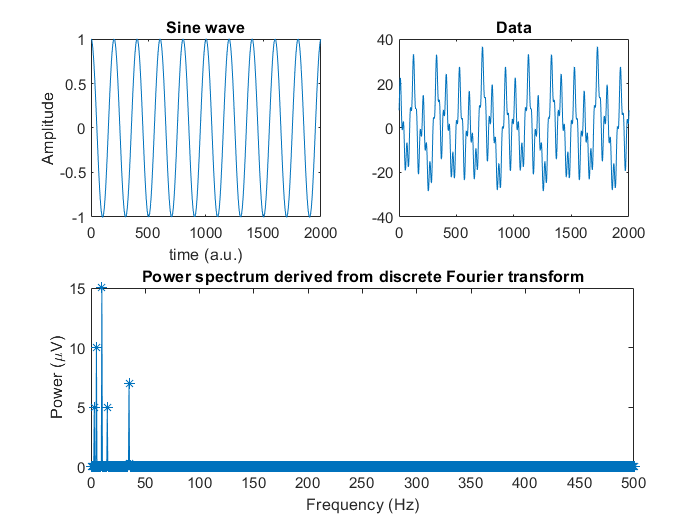

signal  = sum(sine_waves,1); % sum to simplify
N       = length(signal);    % length of sequence
fourierTime = ((1:N)-1)/N;   % "time" used for sine waves
nyquist = srate/2;           % Nyquist frequency -- the highest frequency you can measure in the data

% initialize Fourier output matrix
fourierCoefs = zeros(size(signal)); 

% These are the actual frequencies in Hz that will be returned by the
% Fourier transform. The number of unique frequencies we can measure is
% exactly 1/2 of the number of data points in the time series (plus DC). 
frequencies = linspace(0,nyquist,floor(N/2)+1);


% loop over frequencies
for fi=1:N
    
    % create sine wave for this frequency
    fourierSine = exp( -1i*2*pi*(fi-1).*fourierTime );
    
    % compute dot product as sum of point-wise elements
    fourierCoefs(fi) = sum(fourierSine .* signal);
    
    % note: this can also be expressed as a vector-vector product
    % fourier(fi) = fourierSine*signal';
end

% scale Fourier coefficients to original scale
fourierCoefs = fourierCoefs / N;


figure(1), clf
subplot(221)
plot(real(exp( -2*pi*1i*(10).*fourierTime )))
xlabel('time (a.u.)'), ylabel('Amplitude')
title('Sine wave')

subplot(222)
plot(signal)
title('Data')

subplot(212)
plot(frequencies,abs(fourierCoefs(1:length(frequencies)))*2,'*-')
xlabel('Frequency (Hz)')
ylabel('Power (\muV)')
title('Power spectrum derived from discrete Fourier transform')

## Compare manual Fourier transform with fft

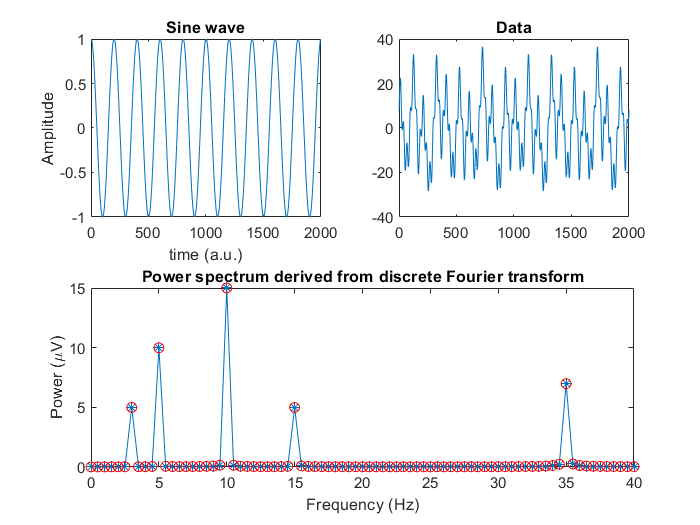

% Compute fourier transform and scale
fourierCoefsF = fft(signal) / N;

subplot(212),hold on
plot(frequencies,abs(fourierCoefsF(1:length(frequencies)))*2,'ro')
set(gca,'xlim',[0 40])

## Compare computation times

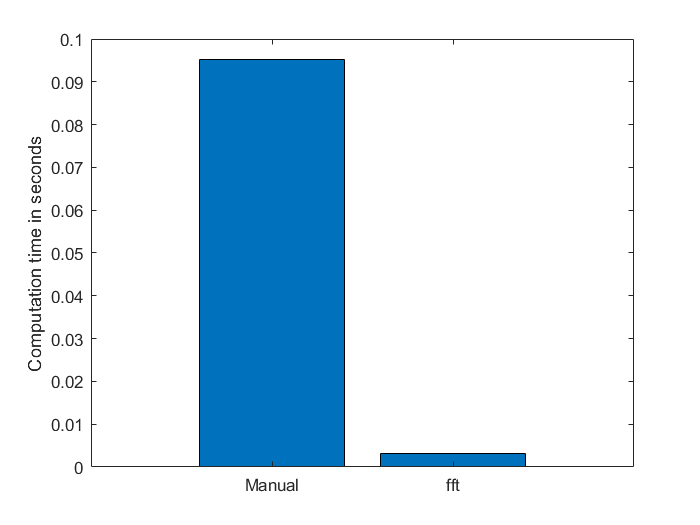

% initialize variable for computation times
computationTimes = zeros(1,2);

% start Matlab's timer
tic;

% manual DTFT
for fi=1:N
    fourierSine = exp( -1i*2*pi*(fi-1).*fourierTime );
    fourierCoefs(fi) = sum( fourierSine .* signal );
end
fourierCoefs = fourierCoefs / N;

% end Matlab's timer
computationTimes(1) = toc;


% now FFT
tic;
fourierCoefsF = fft(signal) / N;
computationTimes(2) = toc;


figure(2), clf

bar(computationTimes)
set(gca,'xtick',1:2,'xticklabel',{'Manual';'fft'},'xlim',[0 3])
ylabel('Computation time in seconds')

## Compute inverse discrete-time Fourier transform

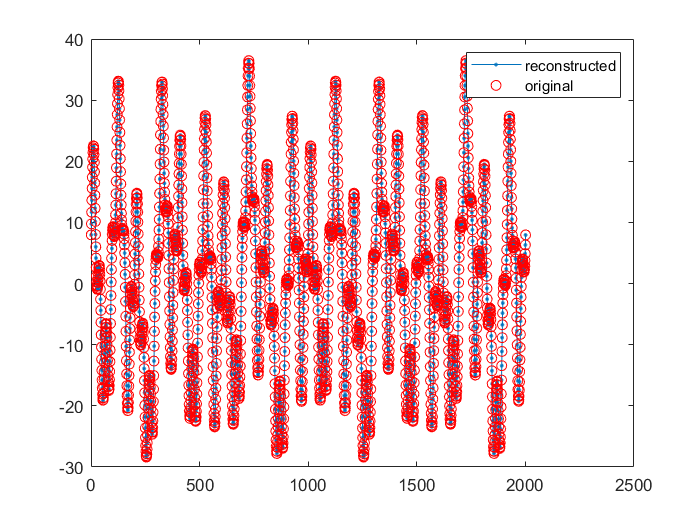

reconSignal = zeros(size(signal));

% loop over frequencies
for fi=1:N
    
    % create sine wave for this frequency
    fourierSine = fourierCoefs(fi) * exp( 1i*2*pi*(fi-1).*fourierTime );
    
    % compute dot product as sum of point-wise elements
    reconSignal = reconSignal + fourierSine;
end

% note: in practice, the inverse Fourier transform should be done using:
reconSignal = ifft(fourierCoefs) * N;

figure(3), clf
plot(real(reconSignal),'.-')
hold on
plot(signal,'ro')

legend({'reconstructed';'original'})

## end.